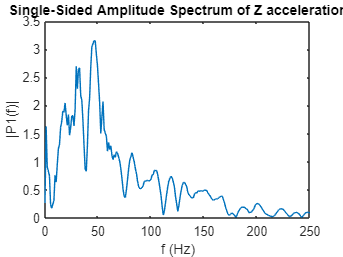

var = new_az(601:1550);

Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = length(var);             % Length of signal
t = (0:L-1)*T;        % Time vector

Y = fft(var);

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;

plot(f,P1) 
title('Single-Sided Amplitude Spectrum of Z acceleration')
xlabel('f (Hz)')
ylabel('|P1(f)|')
xlim([0,250])

clf
plot(rebase_time(var, 1000), var)